% This is the code for calculating the RCS of the chaff particles, modelling them as single dipoles.
% It uses the Monte Carlo distribution modelled by LD for Chaff Distribution to obtain angles and wavelength.

## Parameters

Define global parameters for all simulations

lambda = 10e-2;          % Wavelength in meters (example: 10 cm)
meanLength = lambda / 2; % Mean chaff length
stdDev = 0.01;           % Standard deviation of chaff lengths (1 cm)
minLength = 0.01;        % Minimum chaff length (1 cm)
numParticles = 1000;     % Number of chaff particles

% Orientation parameters
azimuthRange = [0, 2*pi]; % Azimuth angles (radians)
elevationRange = [0, pi]; % Elevation angles (radians)

% Gaussian position distribution parameters
mu = [0, 0, 10]; % Mean position (center at [0, 0, 10])
sigma = [5, 5, 2]; % Standard deviations in X, Y, Z directions

% Monte Carlo bounds for positions
xBounds = [-10, 10];
yBounds = [-10, 10];
zBounds = [0, 20];

## Generate Chaff Lengths

Create chaff lengths using a normal distribution and truncate at minLength

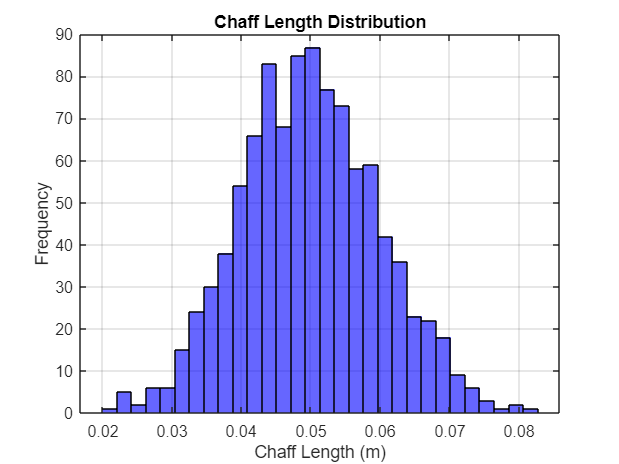

chaffLengths = meanLength + stdDev * randn(numParticles, 1);
chaffLengths(chaffLengths < minLength) = minLength;

% Visualise chaff length distribution
figure;
histogram(chaffLengths, 30, 'FaceColor', 'b', 'EdgeColor', 'k');
title('Chaff Length Distribution');
xlabel('Chaff Length (m)');
ylabel('Frequency');
grid on;

## Monte Carlo Distribution with Orientation

Generate Monte Carlo positions

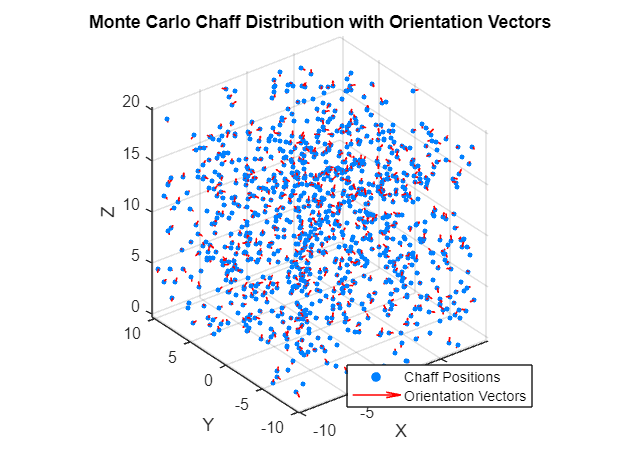

xMC = xBounds(1) + (xBounds(2) - xBounds(1)) * rand(numParticles, 1);
yMC = yBounds(1) + (yBounds(2) - yBounds(1)) * rand(numParticles, 1);
zMC = zBounds(1) + (zBounds(2) - zBounds(1)) * rand(numParticles, 1);

% Generate random orientations for Monte Carlo
azimuthMC = azimuthRange(1) + (azimuthRange(2) - azimuthRange(1)) * rand(numParticles, 1);
elevationMC = elevationRange(1) + (elevationRange(2) - elevationRange(1)) * rand(numParticles, 1);

% Convert orientations to vector components
uMC = cos(azimuthMC) .* sin(elevationMC) .* chaffLengths;
vMC = sin(azimuthMC) .* sin(elevationMC) .* chaffLengths;
wMC = cos(elevationMC) .* chaffLengths;

% Visualise Monte Carlo distribution with orientation
figure;
scatter3(xMC, yMC, zMC, 10, 'filled', 'MarkerFaceColor', [0, 0.5, 1]);
hold on;
quiver3(xMC, yMC, zMC, uMC, vMC, wMC, 0.5, 'Color', 'r', 'LineWidth', 1);
hold off;
title('Monte Carlo Chaff Distribution with Orientation Vectors');
xlabel('X'); ylabel('Y'); zlabel('Z');
legend({'Chaff Positions', 'Orientation Vectors'}, 'Location', 'Best');
grid on; axis equal;

## Average RCS Calculation for a Single Dipole

% azimuthAngles1 = linspace(0, pi, 100);% Azimuth angles from 0 to π radians
% azimuthAngles2 = linspace(0, pi/2, 100);% Azimuth angles from 0 to π/2 radians
% elevationAngles = linspace(-pi, pi, 100); %Elevation angles from 0 to π radians
% 
% % RCS formula for a dipole, assuming sinusoidal variation
% %RCS = (0.3377 * lambda^2 + 0.029 * lambda^2 .* sin(1.9 * azimuthAngles)) / 3;
% %display RCS
% 
% RCS1 = 0.15 * lambda^2;
% 
% RCS2 = (0.0377*(1+0.77*sin(1.9*azimuthAngles)))*lambda^2;
% 
% % Normalize RCS by lambda^2
% normalizedRCS1 = RCS1 / lambda^2;
% normalizedRCS2 = RCS2 / lambda^2;
% 
% % Plot sigma/lambda^2 vs. azimuth angle
% figure;
% plot(azimuthAngles1 * 180/pi, normalizedRCS1, 'b-', 'LineWidth', 2); % Convert azimuth to degrees
% hold on
% plot(azimuthAngles2 * 180/pi, normalizedRCS2, 'b-', 'LineWidth', 2); % Convert azimuth to degrees
% % hold off
% %xlabel('Azimuth Angle \phi (degrees)');
% %ylabel('\sigma / \lambda^2');
% title('Normalized RCS vs. Azimuth Angle');
% grid on;
% 
% % Display average normalized RCS
% averageRCS = mean(RCS);
% disp(['Average RCS of the chaff particles: ', num2str(averageRCS), ' m^2']);

## **Average RCS calculation for N dipoles**

% Define the azimuth angles from 0 to pi/18 radians (from 0 to 1/18*pi)
azimuthAngles1 = linspace(0, 1/18*pi, 100); 

% Define the number of particles
numParticles1 = 50;

% Calculate the RCS with element-wise operations
RCS = 0.15 * numParticles1 + 0.079 * numParticles1^2 .* (23.4 * (numParticles1^(1/3)) .* sin(azimuthAngles1/2)).^2;

% Calculate the average RCS
averageRCS = mean(RCS);

% Display the average RCS
disp('Average RCS of the N chaff particles:');

Average RCS of the N chaff particles:


disp(averageRCS);

   3.7464e+03



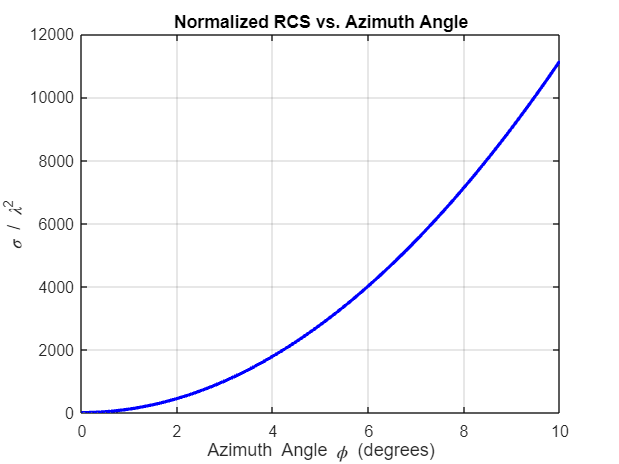


% Create the plot
figure;
plot(azimuthAngles1 * 180 / pi, RCS, 'b-', 'LineWidth', 2);  % Convert azimuth to degrees
xlabel('Azimuth Angle \phi (degrees)');
ylabel('\sigma / \lambda^2');
title('Normalized RCS vs. Azimuth Angle');
grid on;